# Evaluación 9 (Planeación de Trayectorias)

## Daniel Castillo López A01737357

- **Obtener **el mapa de puntos para generar la planeación de trayectorias a partir de tu rostro, marcando **set-****points** con el software Geogebra.

- **Planear** la trayectoria que debe seguir el algoritmo empleando el mapa de puntos obtenido, considerando la descripción más próxima a los rasgos físicos de tu rostro (Forma de la cara, forma del cabello, ojos, cejas, nariz, boca y orejas), (barba en caso de que aplique).

- **Implementar** el código requerido para generar la planeación de trayectorias empleado la técnica que consideres más eficiente para esta aplicación (**Control en lazo abierto, control de posición, control de trayectorias** **ó** **PurePursuit** **(****way-points****)**). Considerando el ajuste de los parámetros cinemáticos del robot móvil como: Velocidad angular (w), velocidad lineal (v), ancho de la muestra (ts), tiempo de simulación (t), ganacias, etc.

#### Geogebra puntos:

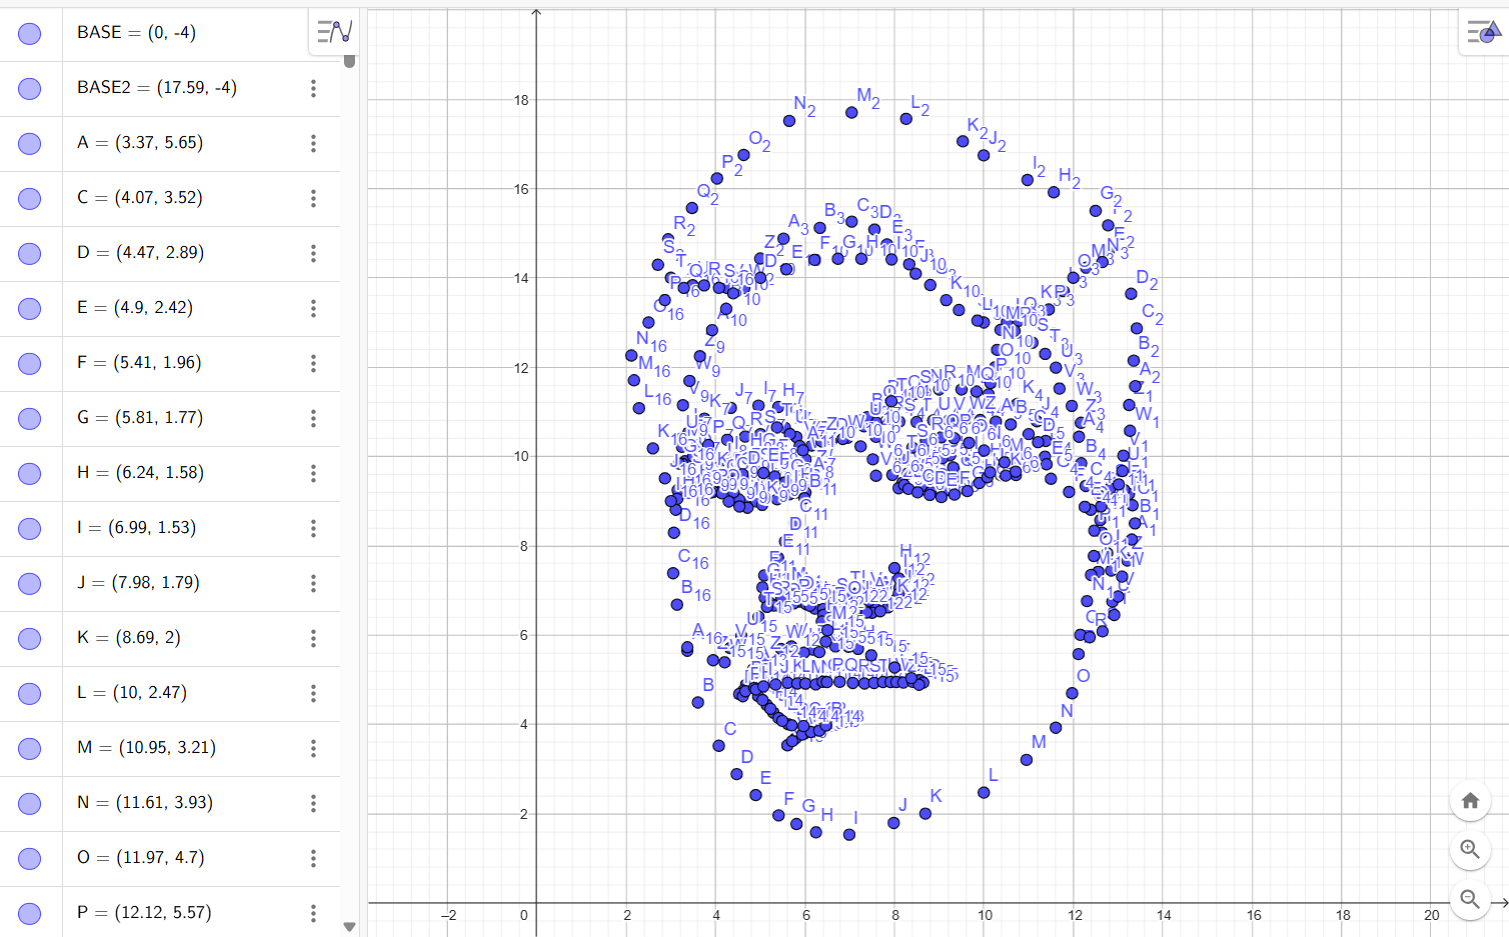

### Justificación

Establecimos el uso de waypoints, por su facilidad de recorrer varios puntos, debdio a que son más de 400 coordenas, esto puede facilitar el trazo de detalles en la dirección de movimiento de nuestro robot, pero con otros métodos, varias coordenadas haran el proceso más tardado, por eso se optó por usar esta estrategia.

## Código: 

Se agrega un objeto DifferentialDrive, que representa el modelo cinemático del robot móvil diferencial.En este caso, se utiliza un robot más pequeño en base a Wheel radius y una base más ancha definida en Wheelbase

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

Se define el tiempo de muestreo sampleTime  y el vector de tiempo tVec, que establece la duración total de la simulación.

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:657;         % Time array
%343
initPose = [6.734200061560114; 11.29938443323006;-45];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;


Cargamos los puntos de referencia en un archivo llamado coords, este archivo es externo, como vi el tamaño original se pierde un poco lo escalo el doble.

% Cargar waypoints desde archivo
run("coords.m");
waypoints = waypoints * 2;


% Create visualizer
%viz = Visualizer2D;
%viz.hasWaypoints = true;

En esta sección calcula las velocidades necesarias para seguir la trayectoria, porque se configura la Distancia de anticpación "LookaheadDistance, en cuanto más grade se puede presentar mejor curvas, también encontrmaos la velocidad lineal deseada y velocidad angular máxima, para mejor las curvas en movimiento pronunciados

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = .5;
controller.MaxAngularVelocity = 4.5;

En cada iteración del bucle, el robot calcula su nueva pose con base en el controlador y su modelo cinemático, primero su cálculo de velocidades de referencia y velocidades de rueda, velocidades en el mundo y actualización de pose y la visualización en teimpo real.

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    %viz(pose(:,idx),waypoints)
    %waitfor(r);
    
end


Este apartado está designado a mostrar la imagen con la trayectoria final

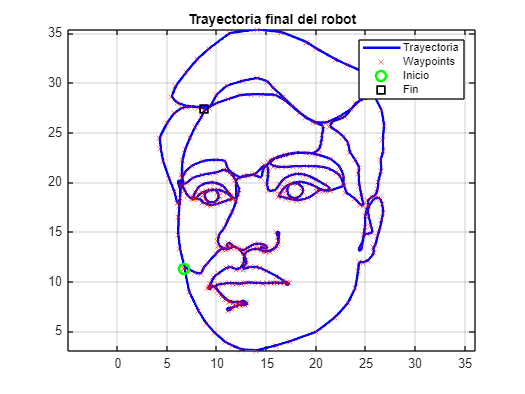

figure
plot(pose(1,:), pose(2,:), 'b-', 'LineWidth', 2)
hold on
plot(waypoints(:,1), waypoints(:,2), 'xr', 'MarkerSize', 6)
plot(pose(1,1), pose(2,1), 'go', 'MarkerSize', 8, 'LineWidth', 2)
plot(pose(1,end), pose(2,end), 'ks', 'MarkerSize', 8, 'LineWidth', 2)
legend('Trayectoria','Waypoints','Inicio','Fin')
title('Trayectoria final del robot')
axis equal
grid on 

### Imagen de referencia: